Cruise system model setup

clear
m = 1000;
b = 50;
s = tf('s');
P_cruise = 1/(m*s+b);    % plant
t_cruise = 0:0.1:30;    % 시뮬 시간    
r_cruise = 10;          % 목표 속도 10

DC motor system model setup

clear
J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
L = 2.75E-6;
R = 4;
s = tf('s');
t_motor = 0:0.001:0.3;
r_motor = 1;
P_motor = K/(s*((J*s+b) * (L*s+R) +K^2));

System selection

t_system = t_motor;
P_system = P_motor;
r_system = r_motor;

P(proportional) control

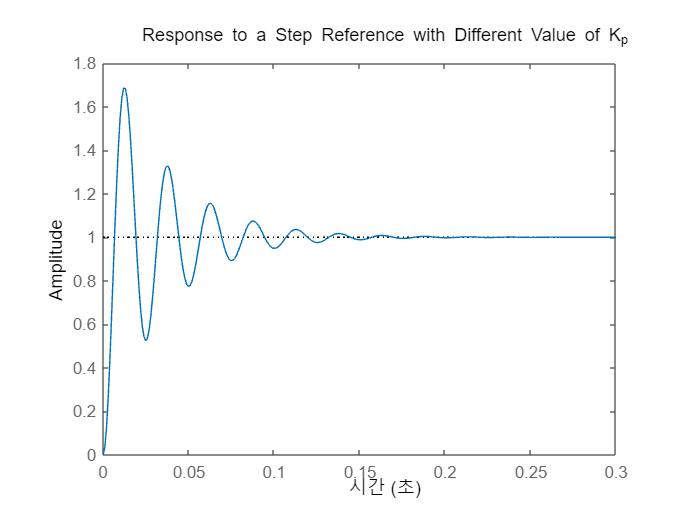

Kp = 30;
C = Kp;
sys_cl = feedback(C*P_system,1); %uniti feedback 이니까
figure(1)
step(r_system*sys_cl,t_system)
ylabel('Amplitude')
title('Response to a Step Reference with Different Value of K_p')

Kp = 30;
C = Kp;
dist_cl = feedback(P_system,C)

dist_cl =
 
                        0.0274
  ---------------------------------------------------
  8.878e-12 s^3 + 1.291e-05 s^2 + 0.0007648 s + 0.822
 
연속시간 전달 함수입니다.
모델 속성


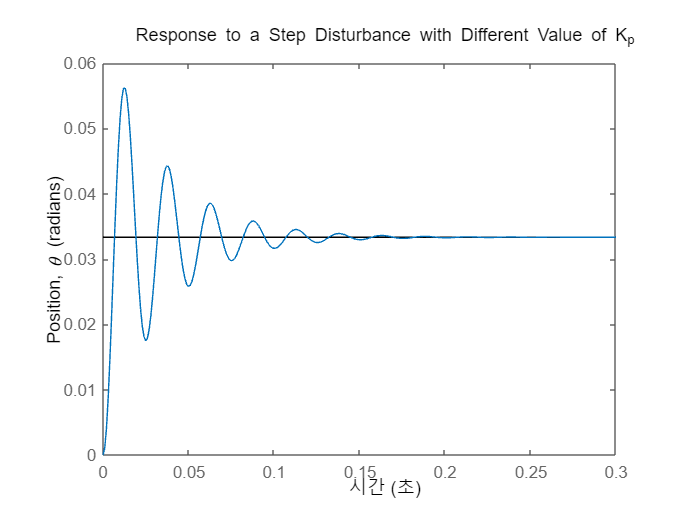

figure(2)
step(dist_cl,t_system)
ylabel('Position, \theta (radians)')
title('Response to a Step Disturbance with Different Value of K_p')

PI control

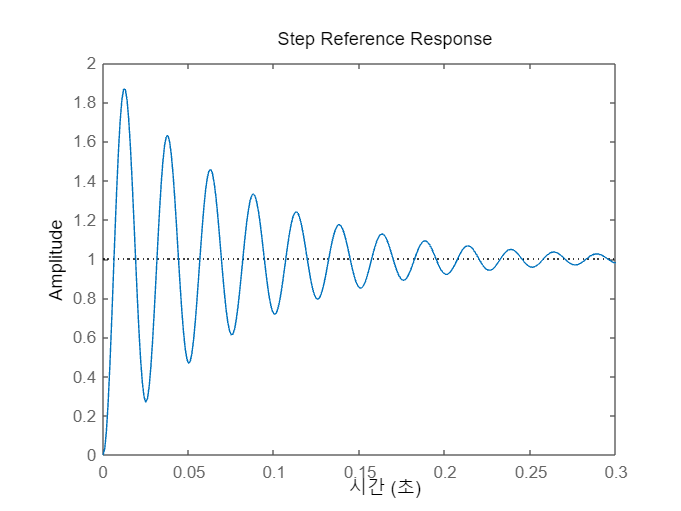

Kp = 30;
Ki = 1000;
C = Kp + Ki/s;
sys_cl = feedback(C*P_system,1); %uniti feedback 이니까
figure(3)
step(r_system*sys_cl,t_system);
ylabel('Amplitude');
title('Step Reference Response');

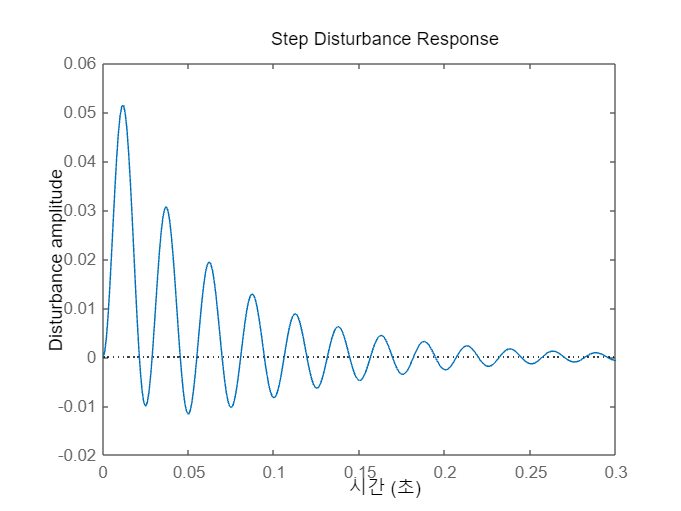

figure(4)
dist_cl = feedback(P_system,C);
step(dist_cl,t_system);
ylabel('Disturbance amplitude');
title('Step Disturbance Response');

PID control

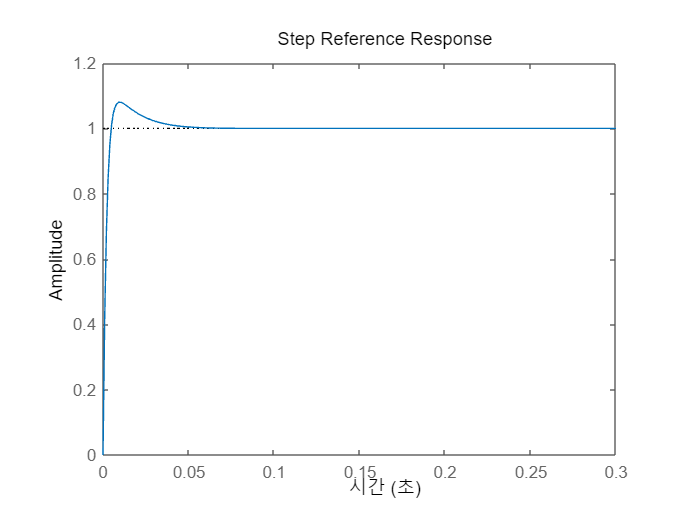

Kp = 30;
Ki = 1000;
Kd = 0.25;
C = Kp + Ki/s + Kd*s;
sys_cl = feedback(C*P_system,1); %uniti feedback 이니까
figure(5)
step(r_system*sys_cl,t_system);
ylabel('Amplitude');
title('Step Reference Response');

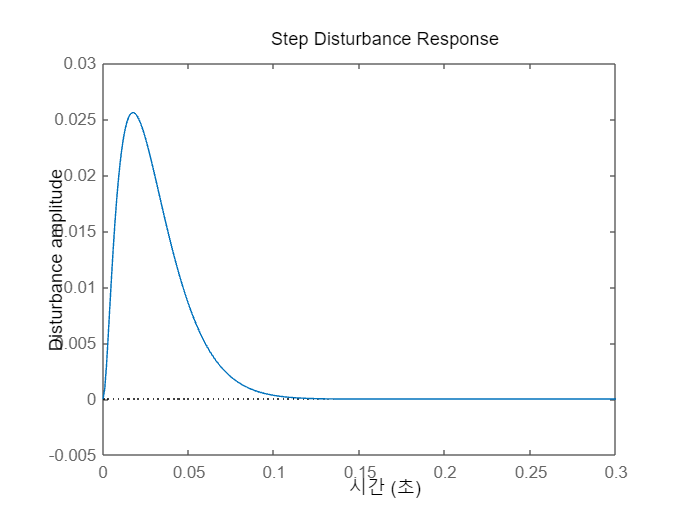

figure(6)
dist_cl = feedback(P_system,C); 
step(dist_cl,t_system)
ylabel('Disturbance amplitude');
title('Step Disturbance Response');

stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.0032
    TransientTime: 0.0316
     SettlingTime: 0.0316
      SettlingMin: 0.9142
      SettlingMax: 1.0802
        Overshoot: 8.0168
       Undershoot: 0
             Peak: 1.0802
         PeakTime: 0.0098


PDI Tuner

% pidTuner(P_system, 'pid')